[I, map] = imread('C:\dev\biomedeng\Associated Files\Chapter 13\blood1.tif')

I = 265×272 uint8 matrix
    46    46    48    56    73    85    96    96   106   113   118   126   131   143   165   171   160   131    85    46    46    46    46    46    46    46    46    46    46    48   101   138   160   181   171   176   160   160   148   155   155   155   155   160   155   155   155   155   155   148
    46    46    48    56    68    80    85   101   101   113   123   126   138   148   165   176   155   123    63    48    46    46    46    46    46    46    46    46    46    46    85   131   155   181   171   176   160   155   143   143   148   148   155   155   155   160   148   155   148   148
    46    46    46    55    68    80    80    90   101   106   113   123   126   143   148   165   143   113    56    46    46    46    46    46    46    46    46    46    46    46    85   131   155   176   171   165   155   155   143   155   148   148   155   148   148   148   155   155   155   155
    46    46    46    48    55    63    73    90   101   106   113   118


map =

     []




b_s = [1 2 1;0 0 0;-1 -2 -1]; %3x3 Horizontal edge filter

I_s_h = imfilter(I, b_s)

I_s_h = 265×272 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     2     5     9    16    31    43    33    23    24    20    16    13    22    40    46    58    82    76    29     0     0     0     0     0     0     0     0     2    20    41    35    22    15    16    27    26    20    15    12    21    21    19    31    33    21     7     0     0     0
     0     2    12    31    51    59    52    34    18    24    35    41    48    52    55    56    45    17     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    10    10     5     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     9    38    74    87    81    77    70    55    40  

I_s_v = imfilter(I, b_s') 

I_s_v = 265×272 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    20   133   242   245    95     2     0     0     0     0     0     0     0     0     0     0     0     0     0    15    33    53    41    22     0     0     0     0     0     5     7     5     0    21    24
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    30   198   255   255    83     4     0     0     0     0     0     0     0     0     0     0     0     0     0    26    49    68    58    29     0     0     0     0     7     0     7     3     0    21    19
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    30   199   255   255    54    11     0     0     0     0     0     0     0     0     0     0     0     0     0    32    54    57    58    19     0     9     0     0     9     0     0     0     0     7    26
     0     0     0     0     0     0     0     0     0     0     0  


I_s_c = imbinarize(I_s_h) | imbinarize(I_s_v)%combined

I_s_c = 265×272 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  


I_s_v_bin = imbinarize(I_s_v, 0.5)%Convert the vertical to binary and adjust

I_s_v_bin = 265×272 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

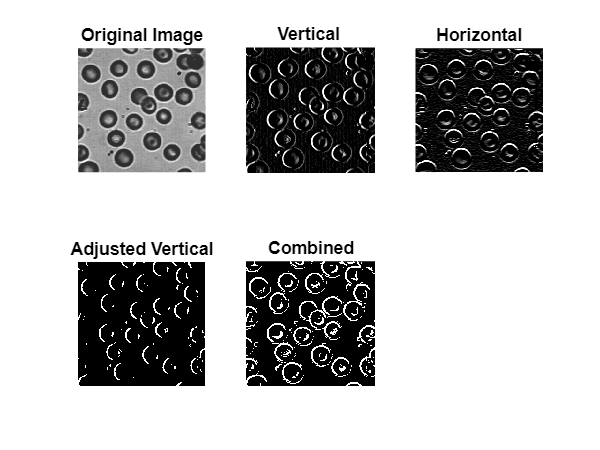

subplot(2,3,1);
imshow(I)
title('Original Image')

subplot(2, 3, 2)
imshow(I_s_v)
title('Vertical ')

subplot(2, 3, 3)
imshow(I_s_h)
title('Horizontal')


subplot(2, 3, 4)
imshow(I_s_v_bin)
title('Adjusted Vertical')


subplot(2, 3, 5)
imshow(I_s_c)
title('Combined')

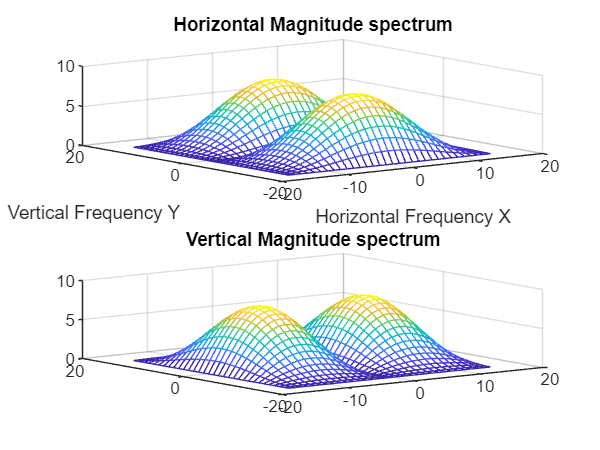

figure;

subplot(2, 1, 1)
F = fftshift(abs(fft2(b_s, 32, 32)));%FT of the combined filter
mesh (-16:15,-16:15,F);
title('Horizontal Magnitude spectrum')
xlabel('Horizontal Frequency X')
ylabel('Vertical Frequency Y')

subplot(2, 1, 2)
F = fftshift(abs(fft2(b_s', 32, 32)));%FT of the combined filter
mesh (-16:15,-16:15,F);
title('Vertical Magnitude spectrum')